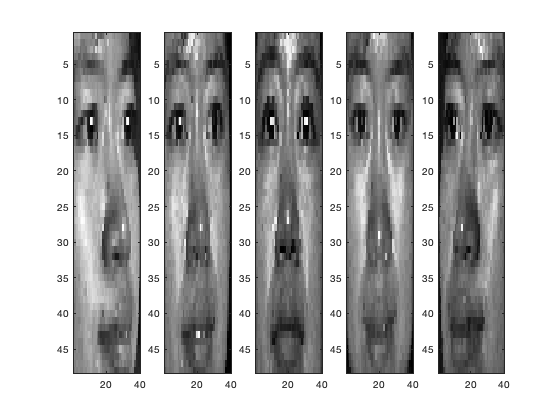

data = load("pose.mat");
pose = data.pose;
figure;
colormap gray
for i = 1:5
    subplot(1,5,i);
    imagesc(pose(:,:,i,1));
end

%Reshape 2D pixels to 1D
n = 68;
dim = 48*40;
poses = 13;
p_new = zeros(n*poses,dim);

for i = 1:n
    for j = 1:poses
        x = pose(:,:,j,i);
        p_new((i-1)+j,:) = x(:)';
    end
end

%Finding the means and centering the data

p_mean = mean(p_new,1);

p_centered = p_new - ones(n*poses,1)*p_mean;

%PCA
nPCA = 68;
[U,Sigma,V] = svd(p_new',"econ");
z = p_new*U(:,1:nPCA);

%MDA

mean_all = mean(z);
mean_class = zeros(n,nPCA);
b_scatter = zeros(nPCA); 
w_scatter = zeros(nPCA);
for i=1:68
    mean_class(i,:) = mean(z((i-1)*poses+1:(i-1)*poses+13,:));
    b_scatter = b_scatter + n*(mean_class(i) - mean_all)*(mean_class(i) - mean_all)';
    w_scatter = w_scatter + (z((i-1)*poses+1:(i-1)*poses+13,:) - ones(poses,1)*mean_class(i,:))'*(z((i-1)*poses+1:(i-1)*poses+13,:) - ones(poses,1)*mean_class(i,:));
end
[eig_vec , eig_val] = eig(b_scatter,w_scatter);
[eig_s, isort] = sort(diag(eig_val),"descend");
eig_vec = eig_vec(:,isort);
W = eig_vec(:,1:n-1);
scaled_down = z*W;

%Split into train and test sets (train = first 10 poses, test = last 3
%poses)
train_set = zeros(n,10,n-1);
test_set = zeros(n,3,n-1);

for i=1:68
    train_set(i,:,:) = scaled_down((i-1)*poses+1:(i-1)*poses+10,:);
    test_set(i,:,:) = scaled_down((i-1)*poses+11:(i-1)*poses+13,:);
end

%k-nearest neighbors
total_errors = 0;
total_test = 0;
for k = 1:100
    for b = 1:n
        errors = 0;
        for i = 1:3
            x_diff = [];
            class = [];
            for j = 1:n
                for m = 1:10
                    x_norm = 0;
                    for l = 1:n-1
                        x_dist = (train_set(j,m,l) - test_set(b,i,l))^2;
                        x_norm = x_norm + x_dist;
                    end
                    x_norm = sqrt(x_norm);
                    x_diff = [x_diff, x_norm];
                    class = [class,j];
                end
            end
            diff_table = array2table(x_diff);
            x_diff = class;
            class_table = array2table(x_diff);
            dist_table = [class_table;diff_table];
            dist_table = rows2vars(dist_table);
            dist_table(:,"OriginalVariableNames") = [];
            sorted = sortrows(dist_table,2);
            nearest = head(sorted,k);
            nearest_array = table2array(nearest);
            pred_class = mode(nearest_array, 1);
            if (pred_class(1) ~= b)
                errors = errors + 1;
            end
        end
        error_rate = errors/length(test_set);
        total_errors = total_errors + errors;
        total_test = total_test + length(test_set);
    end
global_error_rate = total_errors/total_test;
global_accuracy_rate = (total_test - total_errors)/total_test;
fprintf("K-value = %d, Global Accuracy Rate = %d\n",k,global_accuracy_rate);
end

K-value = 1, Global Accuracy Rate = 9.593426e-01
K-value = 2, Global Accuracy Rate = 9.594507e-01
K-value = 3, Global Accuracy Rate = 9.595588e-01
K-value = 4, Global Accuracy Rate = 9.597210e-01
K-value = 5, Global Accuracy Rate = 9.598616e-01
K-value = 6, Global Accuracy Rate = 9.599553e-01
K-value = 7, Global Accuracy Rate = 9.600222e-01
K-value = 8, Global Accuracy Rate = 9.600724e-01
K-value = 9, Global Accuracy Rate = 9.601115e-01
K-value = 10, Global Accuracy Rate = 9.601427e-01
K-value = 11, Global Accuracy Rate = 9.601683e-01
K-value = 12, Global Accuracy Rate = 9.601896e-01
K-value = 13, Global Accuracy Rate = 9.602076e-01
K-value = 14, Global Accuracy Rate = 9.602231e-01
K-value = 15, Global Accuracy Rate = 9.602364e-01
K-value = 16, Global Accuracy Rate = 9.602482e-01
K-value = 17, Global Accuracy Rate = 9.602585e-01
K-value = 18, Global Accuracy Rate = 9.602677e-01
K-value = 19, Global Accuracy Rate = 9.602759e-01
K-value = 20, Global Accuracy Rate = 9.602833e-01
K-value =